# Blackjack Policies

So far we have played physical blackjack and demonstrated the MATLAB blackjack environment by using the interface to generate an interactive game with user-input.

Here we will explore the concept of a learned *policy* to express how an agent can interact with the environment.

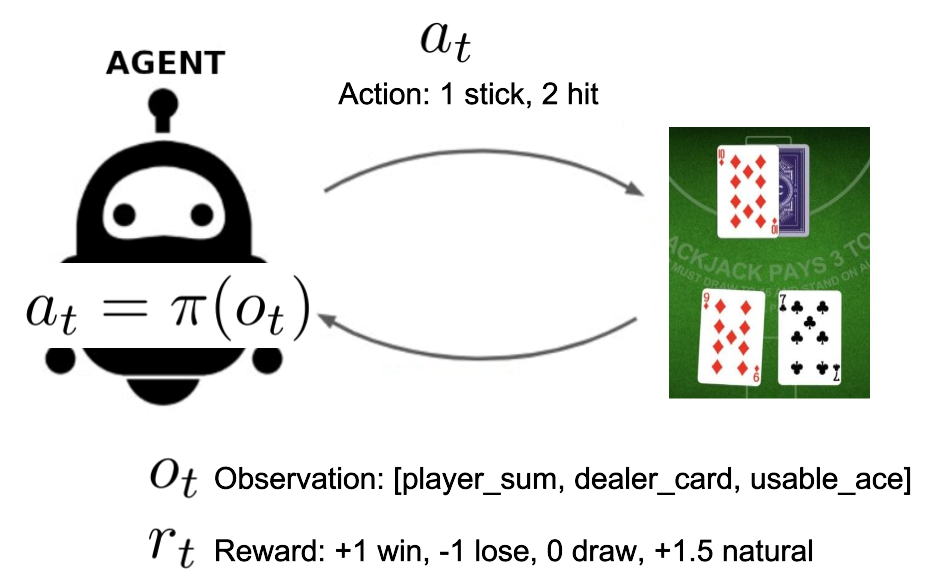

A policy, $\pi$, is a mapping from observations $o_t$ to actions $a_t$,

$a_t = \pi(o_t)$.

For the blackjack game environment, at each step of a hand, the observation is a vector of three numbers: `[player_sum, dealer_card, usable_ace]`

## Random Policy

One way to represent the policy is a function that takes the observation vector as the input argument and returns the scalar action (1:stick, 2: hit).

function action = random_policy(observation)
    action = randi([1, 2]);
end

This function ignores the observation and simply chooses one of the two random actions.

## Policy Evaluation

To avoid repeating ourselves (recall DRY), we can define a function to evaluate the performance of a user-provided policy function.

function [rewards, mu, conf95] = evaluate_policy(policy_fun, N)
    % EVALUATE_POLICY Function to evaluate a user-specified policy over N hands.
    % Syntax:
    %   rewards = evaluate_policy(policy_fun, N)
    % Inputs:
    %   policy_fun - Function handle to the policy that determines the action
    %                to take given the current observation. The function should
    %                have the signature: action = policy_fun(observation)
    %   N          - Integer specifying the number of hands to play.
    %
    % Outputs:
    %   rewards    - Nx1 array containing the rewards for each hand played.
    %   mu         - Mean reward for the sample
    %   conf95     - 1x2 array containing the lower and upper 95%
    %   confidence interval.
    %
    % Example:
    %   % Define a simple policy function
    %   policy_fun = @(obs) randi([0, 1]); % Randomly choose action 0 or 1
    %   
    %   % Evaluate the policy over 100 hands
    %   rewards = evaluate_policy(policy_fun, 100);

    % Initialize the rewards array
    rewards = zeros(N, 1);
    % Intitialize the environment
    env = BlackJackEnv(1);
    % Loop to play N hands
    for ii = 1:N
        % Reset the environment to start a new hand
        obs = env.reset();
        terminated = false;
        
        % Play the hand until it is done
        while ~terminated
            % Choose an action based on the policy
            action = policy_fun(obs);
            
            [observation, reward, terminated, truncated, info] = env.step(action);
            
            % Update the observation
            obs = observation;
        end        
        % Accumulate the reward
        rewards(ii) = reward;
    end

    % Calculate reward statistics and print.
    mu = mean(rewards);
    sem = std(rewards)/sqrt(N);
    conf95 = [mu-(1.95*sem), mu+(1.95*sem)];
    fprintf("Mean reward: %.3f, We are 95%% confident that the mean reward is between %.3f and %.3f\n", ...
            mu, conf95(1), conf95(2));

end

## Evaluate Random Policy

As a baseline for our performance, we can use the evaulation function, pass it a handle to our policy function and review the performance.

[rewards, mean_rewards, conf_inv] = evaluate_policy(@random_policy, 10000);

Mean reward: -0.388, We are 95% confident that the mean reward is between -0.406 and -0.370


Plot the rewards vector for each game and annotate the plot with horizontal lines for the mean and confidence interval.

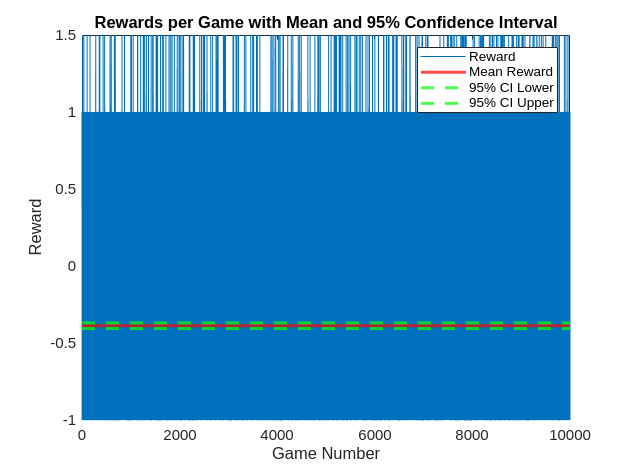

% Plot the rewards vector for each game and annotate the plot with horizontal lines for the mean and confidence interval.
figure();
clf();
plot(rewards, 'DisplayName', 'Reward');
hold on;
yline(mean_rewards, 'r', 'LineWidth', 2, 'DisplayName', 'Mean Reward');
yline(conf_inv(1), 'g--', 'LineWidth', 2, 'DisplayName', '95% CI Lower');
yline(conf_inv(2), 'g--', 'LineWidth', 2, 'DisplayName', '95% CI Upper');
xlabel('Game Number');
ylabel('Reward');
title('Rewards per Game with Mean and 95% Confidence Interval');
legend('show');
hold off;

## A Rule-Based, Expert System Policy

Can you do better than the random policy?

From class, you should have a policy based on your experience and undertanding of the game.  In the field of AI, this type of policy is called an [expert system](https://en.wikipedia.org/wiki/Expert_system). Create a new policy function, following the same signature used in `random_policy` to implement your expert system.  

function action = expert(obs)
    if obs(1) < 17
        action = 2;
    else
        action = 1;
    end
end


Then use the `evaluate_policy` function to determine the performance

[rewards, mean_rewards, conf_inv] = evaluate_policy(@expert, 10000);

Mean reward: -0.054, We are 95% confident that the mean reward is between -0.073 and -0.035


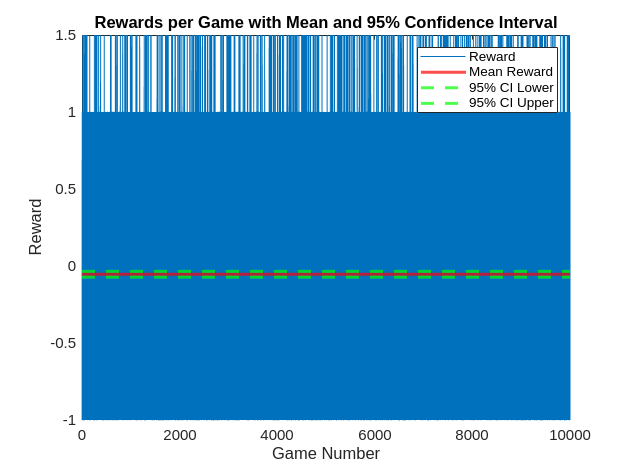

% Plot the rewards vector for each game and annotate the plot with horizontal lines for the mean and confidence interval.
figure();
clf();
plot(rewards, 'DisplayName', 'Reward');
hold on;
yline(mean_rewards, 'r', 'LineWidth', 2, 'DisplayName', 'Mean Reward');
yline(conf_inv(1), 'g--', 'LineWidth', 2, 'DisplayName', '95% CI Lower');
yline(conf_inv(2), 'g--', 'LineWidth', 2, 'DisplayName', '95% CI Upper');
xlabel('Game Number');
ylabel('Reward');
title('Rewards per Game with Mean and 95% Confidence Interval');
legend('show');
hold off;